# Radar Systems Laboratory - A.A. 2022/2023

Master Degree in Telecommunication Engineering, University of Pisa

## Fourth example: CFAR detection | 29-11-2022

This live script loads an acquired data, evaluates the range profile and detect the presence of a target.

### Initialisation and data loading

clear
close all
clc

load('target30.mat')

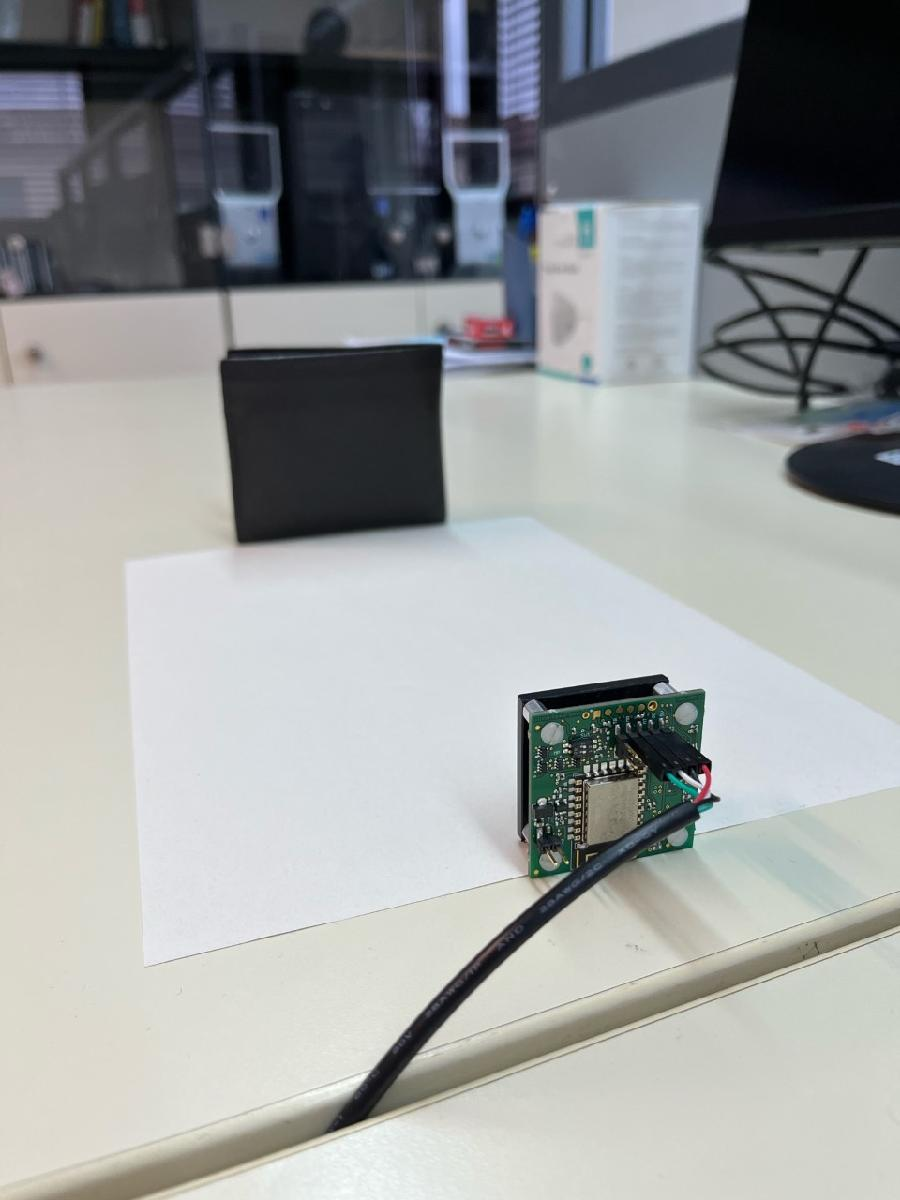

### Radar setting

c = 3e8;
calFactor = 37.5;

zeroPadding = 8;
nfft = zeroPadding*nSamples;

maxRange = ((nSamples + calFactor)*c)/(4*BW);
rangeVec = (0:2*maxRange/nfft:maxRange - maxRange/nfft)*100;

The following equation can be found in the SiRad Simple datasheet: 

$T_{ramp} = t_{smp}\cdot \frac{n\degree  Samples + 37.5}{36MHz}$ , $\qquad \qquad \qquad (1)$ 

where $t_{\textrm{smp}}$ is expressed in clock cycles, the values can be found in the **Table 19 **of the datasheet. The FMCW equation **[1]**:

$\frac{f_b}{\tau} = \frac{B}{T_{ramp}} $ ,$\qquad \qquad \qquad (2)$ 

where $f_b$ is the beat frequency, $\tau \;$is the transit time delay and $B$ is the bandwidth of the system, can be used to calculate the maximum achievable range, by considering that:

$f_b^{max} = \frac{f_s}{2} = \frac{36MHz}{2t_{smp}}$   and   $\tau = \frac{2R_{max}}{c}$ , $\qquad \qquad \qquad (3)$ 

By substituing equations $\left(1\right)$and $\left(3\right)$ in equation $\left(2\right)$, we can write the maximum achievable range:


$$R_{max} = \frac{\left(n\degree  Samples + 37.5\right)\cdot c}{4\cdot B}$$
  
$$\qquad \qquad \qquad (4)$$
 

- **Note: **the "calibration factor" (i.e., 37.5) is different from the one written in the datasheet. 

### Windowing and range compression

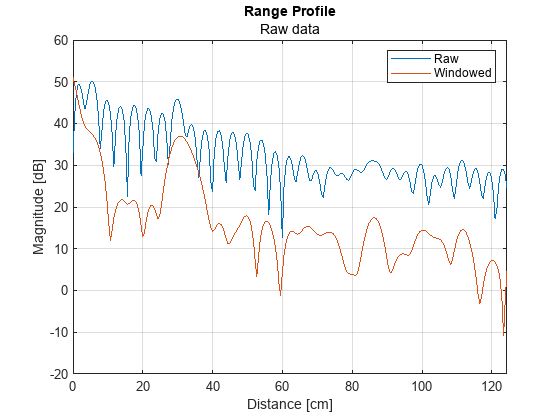

windowKaiser = kaiser(nSamples,5).';

rangeProfile = fft(complexData,nfft);
curveToPlot = abs(rangeProfile(1:end/2));

rangeProfileWKaiser = fft(complexData.*windowKaiser,nfft);
curveToPlotWKaiser = abs(rangeProfileWKaiser(1:end/2));

figure
plot(rangeVec,20*log10(curveToPlot))
hold on
plot(rangeVec,20*log10(curveToPlotWKaiser))
title('Range Profile','Raw data')
xlabel("Distance [cm]")
ylabel("Magnitude [dB]")
xlim([0 rangeVec(end)])
grid on
legend('Raw','Windowed')

### CFAR Detector -  Part 1

Reference **[2]**, Chapter 16

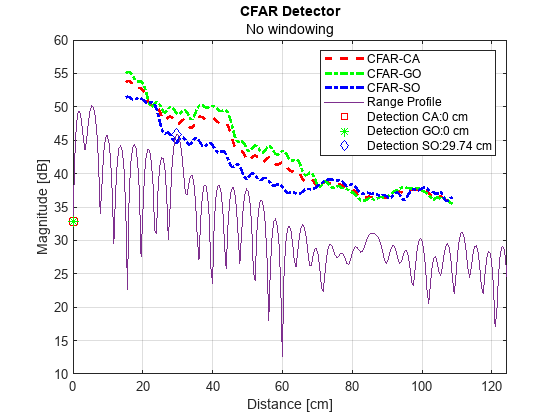

gCell = 12;
eCell = 20;
pFA = 1e-3;

startingCell = gCell + eCell;
endingCell = nfft/2 - gCell - eCell;
alfaCA = pFA^(-1/(2*eCell)) - 1;

[alfaGO,alfaSO] = alfasCalc(2*eCell,pFA);

g_CA = zeros(1,nfft/2);
g_GO = zeros(1,nfft/2);
g_SO = zeros(1,nfft/2);
profileToTest = abs(curveToPlot).^2;

% CFAR thresholds
for kk = startingCell:endingCell
    estLAG = profileToTest(kk - gCell - eCell + 1:kk - gCell);
    estLEAD = profileToTest(kk + gCell:kk + gCell + eCell - 1);
    g_CA(kk) = sum([estLAG,estLEAD],'all');
    g_GO(kk) = max([sum(estLAG),sum(estLEAD)]);
    g_SO(kk) = min([sum(estLAG),sum(estLEAD)]);
end

% Detector
mask = g_CA ~= 0;
[~,detIndCA] = max((curveToPlot.^2 > alfaSO*g_CA).*mask.*curveToPlot);
[~,detIndGO] = max((curveToPlot.^2 > alfaSO*g_GO).*mask.*curveToPlot);
[~,detIndSO] = max((curveToPlot.^2 > alfaSO*g_SO).*mask.*curveToPlot);

figure
plot(rangeVec,10*log10(alfaCA*g_CA),'r--','LineWidth',2)
grid on
hold on
plot(rangeVec,10*log10(alfaGO*g_GO),'g-.','LineWidth',2)
plot(rangeVec,10*log10(alfaSO*g_SO),'b-.','LineWidth',2)
plot(rangeVec,20*log10(curveToPlot))
scatter(rangeVec(detIndCA),20*log10(curveToPlot(detIndCA)),50,'rs')
scatter(rangeVec(detIndGO),20*log10(curveToPlot(detIndGO)),50,'g*')
scatter(rangeVec(detIndSO),20*log10(curveToPlot(detIndSO)),50,'bd')
legend('CFAR-CA','CFAR-GO','CFAR-SO','Range Profile', ...
    strcat('Detection CA: ', num2str(round(rangeVec(detIndCA),2)),' cm'), ...
    strcat('Detection GO: ', num2str(round(rangeVec(detIndGO),2)),' cm'), ...
    strcat('Detection SO: ', num2str(round(rangeVec(detIndSO),2)),' cm'))
title('CFAR Detector','No windowing')
xlabel("Distance [cm]")
ylabel("Magnitude [dB]")
xlim([0 rangeVec(end)])

### CFAR Detector - Part 2

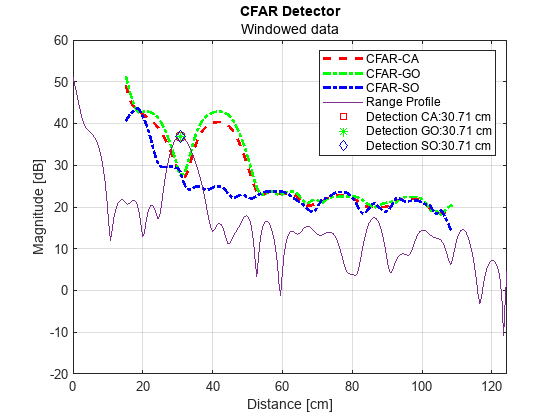

g_CA = zeros(1,nfft/2);
g_GO = zeros(1,nfft/2);
g_SO = zeros(1,nfft/2);
profileToTest = abs(curveToPlotWKaiser).^2;

% CFAR thresholds
for kk = startingCell:endingCell
    estLAG = profileToTest(kk - gCell - eCell + 1:kk - gCell);
    estLEAD = profileToTest(kk + gCell:kk + gCell + eCell - 1);
    g_CA(kk) = sum([estLAG,estLEAD],'all');
    g_GO(kk) = max([sum(estLAG),sum(estLEAD)]);
    g_SO(kk) = min([sum(estLAG),sum(estLEAD)]);
end

% Detector
mask = g_CA ~= 0;
[~,detIndCA] = max((curveToPlotWKaiser.^2 > alfaCA*g_CA).*mask.*curveToPlotWKaiser);
[~,detIndGO] = max((curveToPlotWKaiser.^2 > alfaGO*g_GO).*mask.*curveToPlotWKaiser);
[~,detIndSO] = max((curveToPlotWKaiser.^2 > alfaSO*g_SO).*mask.*curveToPlotWKaiser);

figure
plot(rangeVec,10*log10(alfaCA*g_CA),'r--','LineWidth',2)
grid on
hold on
plot(rangeVec,10*log10(alfaGO*g_GO),'g-.','LineWidth',2)
plot(rangeVec,10*log10(alfaSO*g_SO),'b-.','LineWidth',2)
plot(rangeVec,20*log10(curveToPlotWKaiser))
scatter(rangeVec(detIndCA),20*log10(curveToPlotWKaiser(detIndCA)),50,'rs')
scatter(rangeVec(detIndGO),20*log10(curveToPlotWKaiser(detIndGO)),50,'g*')
scatter(rangeVec(detIndSO),20*log10(curveToPlotWKaiser(detIndSO)),50,'bd')
legend('CFAR-CA','CFAR-GO','CFAR-SO','Range Profile', ...
    strcat('Detection CA: ', num2str(round(rangeVec(detIndCA),2)),' cm'), ...
    strcat('Detection GO: ', num2str(round(rangeVec(detIndGO),2)),' cm'), ...
    strcat('Detection SO: ', num2str(round(rangeVec(detIndSO),2)),' cm'))
title('CFAR Detector','Windowed data')
xlabel("Distance [cm]")
ylabel("Magnitude [dB]")
xlim([0 rangeVec(end)])

### References

**[1] **James A. Scheer, James L. Kurtz (editors). “Coherent Radar Performance Estimation”. Boston: Artech House (1993), ISBN 0-89006-628-0.

**[2] **Richards, M.A. and Scheer, J.A. and Scheer, J. and Holm, W.A. "Principles of Modern Radar: Basic Principles, Volume 1". Institution of Engineering and Technology (2010), ISBN 9781891121524